clc,clear;
%iosr.dsp.ltas command fromChristopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

%Rock 80s

[P1,fs]=audioread("Start Me Up.wav");
[P2,fs]=audioread("You Better You Bet.wav");
[P3,fs]=audioread("The Waiting.wav");
[P4,fs]=audioread("Everybody Wants You.wav");
[P5,fs]=audioread("Eye of the Tiger.wav");
[P6,fs]=audioread("Heat of the Moment.wav");
[P7,fs]=audioread("I Love Rock and Roll.wav");
[P8,fs]=audioread("Photograph Leppard.wav");
[P9,fs]=audioread("Every Breath You Take.wav");
[P10,fs]=audioread("King of Pain.wav");
[P11,fs]=audioread("Jump.wav");
[P12,fs]=audioread("Dancing in the Dark.wav");
[P13,fs]=audioread("Forever Man.wav");
[P14,fs]=audioread("Stages.wav");
[P15,fs]=audioread("Cherry Bomb.wav");
[P16,fs]=audioread("Desire.wav");
[P17,fs]=audioread("Free Fallin.wav");
[P18,fs]=audioread("Mixed Emotions.wav");
[P19,fs]=audioread("Heaven Knows.wav");
[P20,fs]=audioread("With or Without You.wav");



figure
[S1,F]=iosr.dsp.ltas(P1,fs,'noct',6,'graph',true,'units','dB');
hold on;
[S2,F]=iosr.dsp.ltas(P2,fs,'noct',6,'graph',false,'units','dB');
[S3,F]=iosr.dsp.ltas(P3,fs,'noct',6,'graph',false,'units','dB');
[S4,F]=iosr.dsp.ltas(P4,fs,'noct',6,'graph',false,'units','dB');
[S5,F]=iosr.dsp.ltas(P5,fs,'noct',6,'graph',false,'units','dB');
[S6,F]=iosr.dsp.ltas(P6,fs,'noct',6,'graph',false,'units','dB');
[S7,F]=iosr.dsp.ltas(P7,fs,'noct',6,'graph',false,'units','dB');
[S8,F]=iosr.dsp.ltas(P8,fs,'noct',6,'graph',false,'units','dB');
[S9,F]=iosr.dsp.ltas(P9,fs,'noct',6,'graph',false,'units','dB');
[S10,F]=iosr.dsp.ltas(P10,fs,'noct',6,'graph',false,'units','dB');
[S11,F]=iosr.dsp.ltas(P11,fs,'noct',6,'graph',false,'units','dB');
[S12,F]=iosr.dsp.ltas(P12,fs,'noct',6,'graph',false,'units','dB');
[S13,F]=iosr.dsp.ltas(P13,fs,'noct',6,'graph',false,'units','dB');
[S14,F]=iosr.dsp.ltas(P14,fs,'noct',6,'graph',false,'units','dB');
[S15,F]=iosr.dsp.ltas(P15,fs,'noct',6,'graph',false,'units','dB');
[S16,F]=iosr.dsp.ltas(P16,fs,'noct',6,'graph',false,'units','dB');
[S17,F]=iosr.dsp.ltas(P17,fs,'noct',6,'graph',false,'units','dB');
[S18,F]=iosr.dsp.ltas(P18,fs,'noct',6,'graph',false,'units','dB');
[S19,F]=iosr.dsp.ltas(P19,fs,'noct',6,'graph',false,'units','dB');
[S20,F]=iosr.dsp.ltas(P20,fs,'noct',6,'graph',false,'units','dB');



S=[S1(:), S2(:),S3(:),S4(:),S5(:),S6(:),S7(:),S8(:),S9(:),S10(:),S11(:),S12(:),S13(:),S14(:),S15(:),S16(:),S17(:),S18(:),S19(:),S20(:)];
S=S.';
MS=mean(S);




%plot(F,MS,LineWidth=2,Color='r');
%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.


hold on;
MS=MS.'

MS =   -61.5582
  -60.4999
  -56.0713
  -47.0945
  -39.9901
  -36.9860
  -36.6474
  -36.8469
  -36.5783
  -36.3626


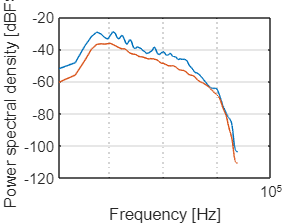

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end




%Rock 2000s


[P21,fz]=audioread("Stiff Upper Lip.wav");
[P22,fz]=audioread("Kryptonite.wav");
[P23,fz]=audioread("Loser.wav");
[P24,fz]=audioread("Rock N Roll Train.wav");
[P25,fz]=audioread("The Pretender.wav");
[P26,fz]=audioread("Dani California.wav");
[P27,fz]=audioread("Save Me.wav");
[P28,fz]=audioread("Be Yourself.wav");
[P29,fz]=audioread("Uprising.wav");
[P30,fz]=audioread("Viva la Vida.wav");
[P31,fz]=audioread("Beautiful Day.wav");
[P32,fz]=audioread("It's My Life.wav");
[P33,fz]=audioread("Supermassive Black Hole.wav");
[P34,fz]=audioread("Sex on Fire.wav");
[P35,fz]=audioread("Seven Nation Army.wav");
[P36,fz]=audioread("How You Remind Me.wav");
[P37,fz]=audioread("American Idiot.wav");
[P38,fz]=audioread("Bring Me to Life.wav");
[P39,fz]=audioread("Photograph.wav");
[P40,fz]=audioread("Use Somebody.wav");

figure
[PP1,FZ]=iosr.dsp.ltas(P21,fz,'noct',6,'graph',true,'units','dB');
hold on;
[PP2,FZ]=iosr.dsp.ltas(P22,fz,'noct',6,'graph',false,'units','dB');
[PP3,FZ]=iosr.dsp.ltas(P23,fz,'noct',6,'graph',false,'units','dB');
[PP4,FZ]=iosr.dsp.ltas(P24,fz,'noct',6,'graph',false,'units','dB');
[PP5,FZ]=iosr.dsp.ltas(P25,fz,'noct',6,'graph',false,'units','dB');
[PP6,FZ]=iosr.dsp.ltas(P26,fz,'noct',6,'graph',false,'units','dB');
[PP7,FZ]=iosr.dsp.ltas(P27,fz,'noct',6,'graph',false,'units','dB');
[PP8,FZ]=iosr.dsp.ltas(P28,fz,'noct',6,'graph',false,'units','dB');
[PP9,FZ]=iosr.dsp.ltas(P29,fz,'noct',6,'graph',false,'units','dB');
[PP10,FZ]=iosr.dsp.ltas(P30,fz,'noct',6,'graph',false,'units','dB');
[PP11,FZ]=iosr.dsp.ltas(P31,fz,'noct',6,'graph',false,'units','dB');
[PP12,FZ]=iosr.dsp.ltas(P32,fz,'noct',6,'graph',false,'units','dB');
[PP13,FZ]=iosr.dsp.ltas(P33,fz,'noct',6,'graph',false,'units','dB');
[PP14,FZ]=iosr.dsp.ltas(P34,fz,'noct',6,'graph',false,'units','dB');
[PP15,FZ]=iosr.dsp.ltas(P35,fz,'noct',6,'graph',false,'units','dB');
[PP16,FZ]=iosr.dsp.ltas(P36,fz,'noct',6,'graph',false,'units','dB');
[PP17,FZ]=iosr.dsp.ltas(P37,fz,'noct',6,'graph',false,'units','dB');
[PP18,FZ]=iosr.dsp.ltas(P38,fz,'noct',6,'graph',false,'units','dB');
[PP19,FZ]=iosr.dsp.ltas(P39,fz,'noct',6,'graph',false,'units','dB');
[PP20,FZ]=iosr.dsp.ltas(P40,fz,'noct',6,'graph',false,'units','dB');



P2000=[PP1(:), PP2(:),PP3(:),PP4(:),PP5(:),PP6(:),PP7(:),PP8(:),PP9(:),PP10(:),PP11(:),PP12(:),PP13(:),PP14(:),PP15(:),PP16(:),PP17(:),PP18(:),PP19(:),PP20(:)];
P2000=P2000.';
MP2000=mean(P2000);




plot(FZ,MP2000,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

hold on;
MP2000=MP2000.'

MP2000 =   -56.8735
  -54.7374
  -47.0317
  -38.4002
  -33.3568
  -31.4277
  -31.0560
  -31.5130
  -31.9388
  -32.2237


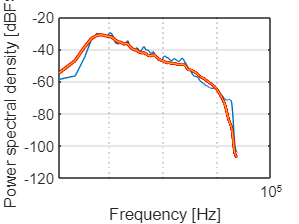

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

%Rock 2020s


[P41,fq]=audioread("Oh Yeah.wav");
[P42,fq]=audioread("Shame Shame.wav");
[P43,fq]=audioread("Death by Rock and Roll.wav");
[P44,fq]=audioread("Unforgettable.wav");
[P45,fq]=audioread("Won't Stand Down.wav");
[P46,fq]=audioread("Planet Zero.wav");
[P47,fq]=audioread("Lost.wav");
[P48,fq]=audioread("Surrender.wav");
[P49,fq]=audioread("Making a Fire.wav");
[P50,fq]=audioread("Kill the Noise.wav");
[P51,fq]=audioread("Alone Again.wav");
[P52,fq]=audioread("Waiting on a War.wav");
[P53,fq]=audioread("Under the Graveyard.wav");
[P54,fq]=audioread("Shot in the Dark.wav");
[P55,fq]=audioread("Breath Again.wav");
[P56,fq]=audioread("American Crisis.wav");
[P57,fq]=audioread("Songs Of Surrender.wav");
[P58,fq]=audioread("Nightshift.wav");
[P59,fq]=audioread("Supermodel.wav");
[P60,fq]=audioread("Lifetime.wav");

figure
[Q1,FQ]=iosr.dsp.ltas(P41,fq,'noct',6,'graph',true,'units','dB');
hold on;
[Q2,FQ]=iosr.dsp.ltas(P42,fq,'noct',6,'graph',false,'units','dB');
[Q3,FQ]=iosr.dsp.ltas(P43,fq,'noct',6,'graph',false,'units','dB');
[Q4,FQ]=iosr.dsp.ltas(P44,fq,'noct',6,'graph',false,'units','dB');
[Q5,FQ]=iosr.dsp.ltas(P45,fq,'noct',6,'graph',false,'units','dB');
[Q6,FQ]=iosr.dsp.ltas(P46,fq,'noct',6,'graph',false,'units','dB');
[Q7,FQ]=iosr.dsp.ltas(P47,fq,'noct',6,'graph',false,'units','dB');
[Q8,FQ]=iosr.dsp.ltas(P48,fq,'noct',6,'graph',false,'units','dB');
[Q9,FQ]=iosr.dsp.ltas(P49,fq,'noct',6,'graph',false,'units','dB');
[Q10,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');
[Q11,FQ]=iosr.dsp.ltas(P51,fq,'noct',6,'graph',false,'units','dB');
[Q12,FQ]=iosr.dsp.ltas(P52,fq,'noct',6,'graph',false,'units','dB');
[Q13,FQ]=iosr.dsp.ltas(P53,fq,'noct',6,'graph',false,'units','dB');
[Q14,FQ]=iosr.dsp.ltas(P54,fq,'noct',6,'graph',false,'units','dB');
[Q15,FQ]=iosr.dsp.ltas(P55,fq,'noct',6,'graph',false,'units','dB');
[Q16,FQ]=iosr.dsp.ltas(P56,fq,'noct',6,'graph',false,'units','dB');
[Q17,FQ]=iosr.dsp.ltas(P57,fq,'noct',6,'graph',false,'units','dB');
[Q18,FQ]=iosr.dsp.ltas(P58,fq,'noct',6,'graph',false,'units','dB');
[Q19,FQ]=iosr.dsp.ltas(P59,fq,'noct',6,'graph',false,'units','dB');
[Q20,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');

P2020=[Q1(:), Q2(:),Q3(:),Q4(:),Q5(:),Q6(:),Q7(:),Q8(:),Q9(:),Q10(:),Q11(:),Q12(:),Q13(:),Q14(:),Q15(:),Q16(:),Q17(:),Q18(:),Q19(:),Q20(:)];
P2020=P2020.';
MP2020=mean(P2020);




plot(FQ,MP2020,LineWidth=2,Color='r');
%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.


hold on;
MP2020=MP2020.'

MP2020 =   -55.1711
  -53.0009
  -45.6511
  -36.3551
  -31.7328
  -30.0341
  -29.6549
  -30.5836
  -31.3229
  -31.6982


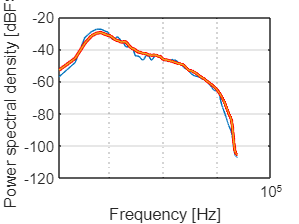

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end



figure()
%legend('Pop 2020s','Pop 2000s', 'Pop 80s')
MP2020=MP2020.'

MP2020 =   -55.1711  -53.0009  -45.6511  -36.3551  -31.7328  -30.0341  -29.6549  -30.5836  -31.3229  -31.6982  -33.0020  -34.0874  -34.5267  -34.9473  -35.5142  -35.5489  -35.3269  -35.4442  -36.0134  -36.8882  -37.8971  -38.6623  -39.2498  -39.6333  -39.7888  -40.0467  -40.5344  -40.9822  -41.2861  -41.5410  -41.7530  -41.8873  -41.9917  -42.1449  -42.3332  -42.4528  -42.4600  -42.4423  -42.5010  -42.6310  -42.7588  -42.8497  -42.9392  -43.0774  -43.2698  -43.4675  -43.6049  -43.6488  -43.6235  -43.5903


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MP2000=MP2000.'

MP2000 =   -56.8735  -54.7374  -47.0317  -38.4002  -33.3568  -31.4277  -31.0560  -31.5130  -31.9388  -32.2237  -32.9571  -34.2100  -35.1043  -35.6026  -35.7048  -36.3019  -36.8034  -36.6647  -36.4482  -36.8761  -37.8284  -38.6115  -39.2543  -39.8388  -40.1908  -40.3764  -40.5117  -40.5960  -40.7938  -41.2225  -41.6879  -41.9646  -42.0664  -42.1410  -42.2428  -42.2974  -42.2635  -42.2281  -42.3026  -42.4967  -42.7346  -42.9539  -43.1500  -43.3468  -43.5546  -43.7582  -43.9295  -44.0470  -44.1081  -44.1242


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MS=MS.'

MS =   -61.5582  -60.4999  -56.0713  -47.0945  -39.9901  -36.9860  -36.6474  -36.8469  -36.5783  -36.3626  -37.1476  -37.7626  -38.5087  -39.1067  -39.5125  -39.7940  -39.7389  -39.9475  -40.6370  -41.4293  -42.0900  -42.3957  -42.6808  -43.0068  -43.0899  -43.0967  -43.2637  -43.4888  -43.7424  -44.0842  -44.4149  -44.5817  -44.5995  -44.6270  -44.7378  -44.8479  -44.8970  -44.9548  -45.0992  -45.2969  -45.4557  -45.5396  -45.5962  -45.6932  -45.8491  -46.0164  -46.1190  -46.1121  -46.0175  -45.9065


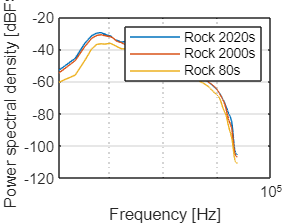

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

hold on
legend('Rock 2020s', 'Rock 2000s', 'Rock 80s')
%plot(FZ,MP2000,LineWidth=2,Color='r');
hold off

function y = rearrange(x,order,shape)
%REARRANGE reshape and permute to make target dim column
    y = permute(x,order);
    y = reshape(y,shape);
end

function y = irearrange(x,order,shape)
%IREARRANGE reshape and permute to original size
    y = reshape(x,shape);
    y = ipermute(y,order);
end

%Functions from
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

`The MIT License (MIT)`

`Copyright (c) 2016 Institute of Sound Recording`

`Permission is hereby granted, free of charge, to any person obtaining a copy`

`of this software and associated documentation files (the "Software"), to deal`

`in the Software without restriction, including without limitation the rights`

`to use, copy, modify, merge, publish, distribute, sublicense, and/or sell`

`copies of the Software, and to permit persons to whom the Software is`

`furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all`

`copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR`

`IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,`

`FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE`

`AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER`

`LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,`

`OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE`

`SOFTWARE.`